Declaration of variables

clc;
clear;

Road_length = 1000;
car_number   = 15

car_number = 15

acceleration =6

acceleration = 6

deceleration =-3.5

deceleration = -3.5000

%initial speed
u = 5

u = 5

%time limitis
time =500

time = 500

%limit speed
lim = 10

lim = 10

%initial position of car
J = 1:car_number

J =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15


A = rand(1,car_number).*Road_length

A =   988.5679  686.1816  376.6892  504.3243  763.4957   48.8748  725.9277  701.3281  458.8908  582.2948  339.0898  170.6254  399.1934  919.7772  226.0454


x(J,1)= sort(A)

x =    48.8748
  170.6254
  226.0454
  339.0898
  376.6892
  399.1934
  458.8908
  504.3243
  582.2948
  686.1816


v(J,1)=randi([0,car_number],car_number,1)

v =      5
     5
     1
     8
    13
    14
    11
     6
     4
    11


%minimum distance between cars
x0 = Road_length/car_number

x0 = 66.6667

num = car_number-1

num = 14

%
average(1) =0

average = 0

initialize road

for T=2:time
    for J=1:car_number
        if J == car_number
            dis(J,T) = x(1,T-1)-x(J,T-1);
        else
            dis(J,T) = x(J+1,T-1)-x(J,T-1);
        end
        if dis(J,T)<0
            dis(J,T) = Road_length+dis(J,T);
        end
        if dis(J,T) > x0
           v(J,T)=v(J,T-1) + acceleration;
        elseif dis(J,T) <= deceleration
            dis(J,T)=0;
            v(J,T)=0;
        else
           v(J,T)=v(J,T-1)+ deceleration;
        end
        if v(J,T)<0
            v(J,T)=0;
        end
        if v(J,T)>lim
            v(J,T)=lim;
        end
        x(J,T)=x(J,T-1)+v(J,T);
        if x(J,T) > Road_length
           x(J,T)=x(J,T)- Road_length;
        end
    end
      max_speed(T) = max(v(J,T));
      min_speed(T) = min(v(J,T));
      average(T) = sum(v(:,T)) / car_number;
end
x(J,T)=x(J,T)

x =    48.8748   58.8748   68.8748   78.8748   88.8748   98.8748  108.8748  118.8748  128.8748  138.8748  148.8748  158.8748  168.8748  178.8748  185.3748  188.3748  188.3748  188.3748  188.3748  188.3748  188.3748  188.3748  194.3748  204.3748  214.3748  224.3748  230.8748  233.8748  233.8748  233.8748  233.8748  233.8748  233.8748  233.8748  233.8748  233.8748  233.8748  233.8748  233.8748  239.8748  249.8748  259.8748  269.8748  279.8748  289.8748  299.8748  309.8748  319.8748  329.8748  339.8748
  170.6254  172.1254  172.1254  178.1254  188.1254  198.1254  208.1254  218.1254  228.1254  234.6254  237.6254  237.6254  237.6254  237.6254  237.6254  237.6254  237.6254  237.6254  237.6254  243.6254  253.6254  263.6254  273.6254  280.1254  283.1254  283.1254  283.1254  283.1254  283.1254  283.1254  283.1254  283.1254  283.1254  283.1254  283.1254  283.1254  289.1254  299.1254  309.1254  319.1254  329.1254  339.1254  349.1254  359.1254  369.1254  379.1254  389.1254  399.1254  409.1254  419

v(J,T)=v(J,T)

v =     5.0000   10.0000   10.0000   10.0000   10.0000   10.0000   10.0000   10.0000   10.0000   10.0000   10.0000   10.0000   10.0000   10.0000    6.5000    3.0000         0         0         0         0         0         0    6.0000   10.0000   10.0000   10.0000    6.5000    3.0000         0         0         0         0         0         0         0         0         0         0         0    6.0000   10.0000   10.0000   10.0000   10.0000   10.0000   10.0000   10.0000   10.0000   10.0000   10.0000
    5.0000    1.5000         0    6.0000   10.0000   10.0000   10.0000   10.0000   10.0000    6.5000    3.0000         0         0         0         0         0         0         0         0    6.0000   10.0000   10.0000   10.0000    6.5000    3.0000         0         0         0         0         0         0         0         0         0         0         0    6.0000   10.0000   10.0000   10.0000   10.0000   10.0000   10.0000   10.0000   10.0000   10.0000   10.0000   10.0000   10.0000   10

average(T) = average(T) 

average =          0    7.6333    6.4667    5.4333    4.6667    5.4667    5.7667    6.1000    6.2000    5.5333    5.0667    4.6667    5.2333    5.5333    4.8667    4.8000    4.2000    4.5333    4.6667    5.0000    5.0667    4.4333    5.0000    5.1000    5.2667    5.7333    5.7667    6.1000    5.9667    6.5333    6.6667    6.4333    6.6000    6.4333    6.3667    6.2000    6.1667    6.2000    5.7667    5.9333    5.7667    5.9333    6.0000    5.7667    5.9333    6.0000    6.1667    6.2000    6.1667    6.2000


d_av = average(1,time-300:time)

d_av =     6.4333    6.2000    6.1667    6.2000    6.0000    6.1667    6.2000    6.1667    6.2000    6.4000    6.4333    6.2000    6.1667    6.2000    6.4000    6.4333    6.6000    6.4333    6.2000    6.1667    6.2000    6.1667    6.2000    6.0000    6.1667    6.2000    6.4000    6.4333    6.2000    6.1667    6.2000    6.1667    6.2000    6.4000    6.4333    6.6000    6.4333    6.2000    6.1667    6.2000    6.0000    6.1667    6.2000    6.1667    6.2000    6.4000    6.4333    6.2000    6.1667    6.2000


av = mean(d_av)

av = 6.2622

Plot

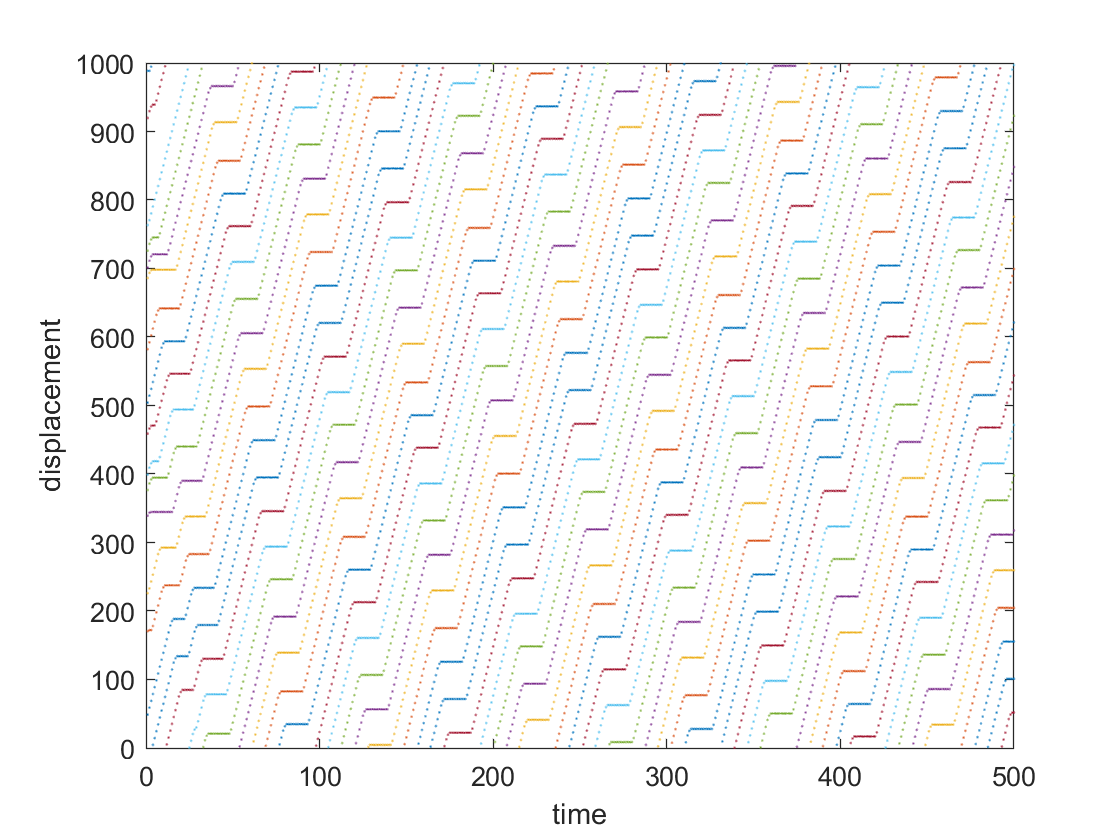

plot(x(1,:),".","MarkerSize",2);
hold on
for b = 2: car_number
    plot(x(b,:),".","MarkerSize",2)
end
xlabel('time')
ylabel('displacement')
hold off;

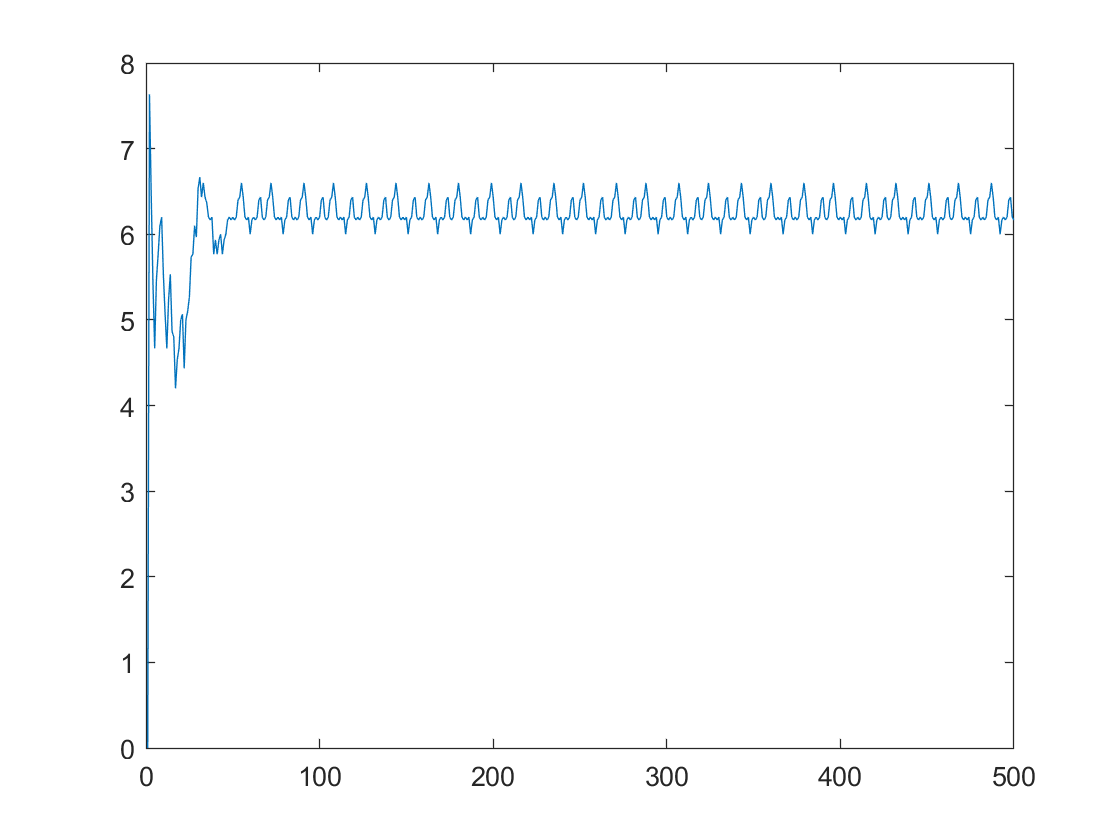


plot(average)